clear all 
clc

Загружаем данные из фала

%% Set up the Import Options and import the data
opts = delimitedTextImportOptions("NumVariables", 4);

% Specify range and delimiter
opts.DataLines = [1, Inf];
opts.Delimiter = "\t";

% Specify column names and types
opts.VariableNames = ["t1", "v1", "t2", "v2"];
opts.VariableTypes = ["double", "double", "double", "double"];

% Specify file level properties
opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";

% Import the data
Miror = readtable("зеркало.txt", opts);
Stand = readtable("стенд.txt", opts);
TestMom = readtable("тест5мН.txt", opts);
Scan  = readtable("скан.txt", opts);

%% Clear temporary variables
clear opts

i = 8500;

TestMomMean = (TestMom.v2(400:i+400))+168;
MirorMean = (Miror.v2(340:i+340))+150;
StandMean = (Stand.v2);
ScanMean = (Scan.v2)+185;



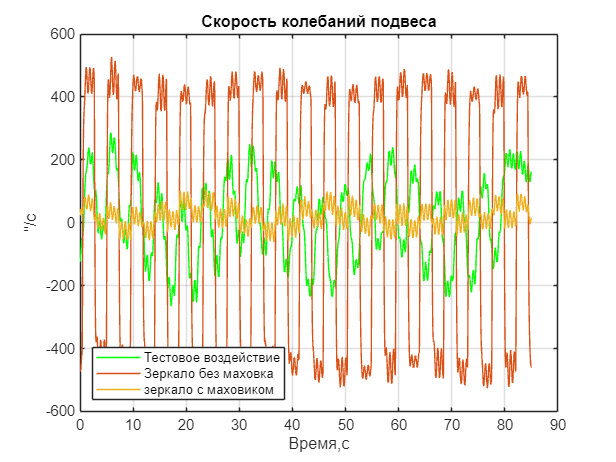

t = 0:0.01:10000;
figure
plot(t(1:i),TestMomMean(1:i), "green");
grid on
hold on
plot(t(1:i), MirorMean(1:i));
plot(t(1:i), ScanMean(1:i));
legend('Тестовое воздействие', 'Зеркало без маховка', 'зеркало с маховиком','Location', "southwest")
xlabel("Время,с")
ylabel("''/c")
title("Скорость колебаний подвеса");
hold off

Вычислим производную как разность соседних отсчетов деленные на шащ времен t = 0.01c

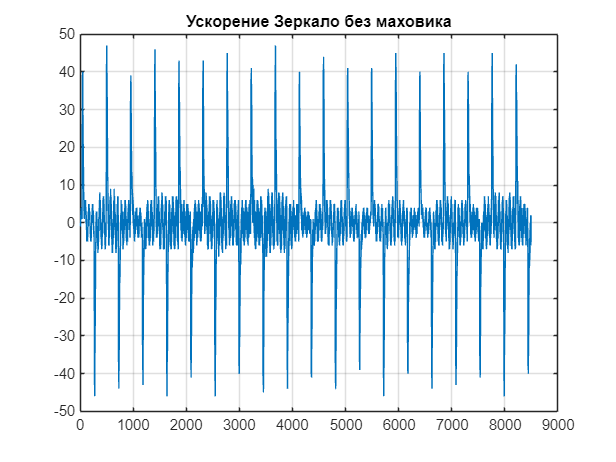

TestMomAcc = diff(TestMomMean(1:i));
MirorAcc = diff(MirorMean(1:i));
ScanAcc = diff(ScanMean(1:i));

figure
plot(MirorAcc);
grid on
title("Ускорение Зеркало без маховика");

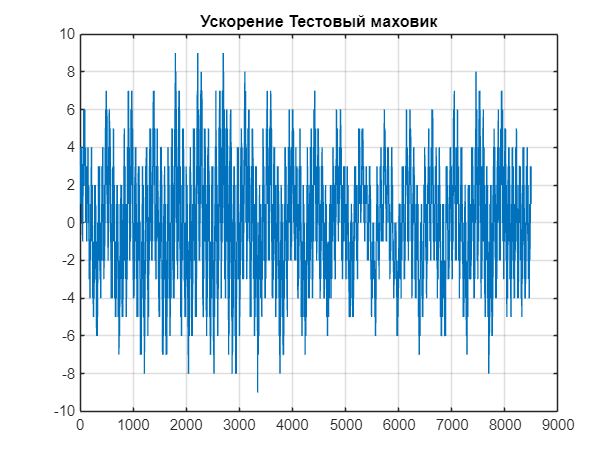


figure
plot(TestMomAcc);
grid on
title("Ускорение Тестовый маховик");

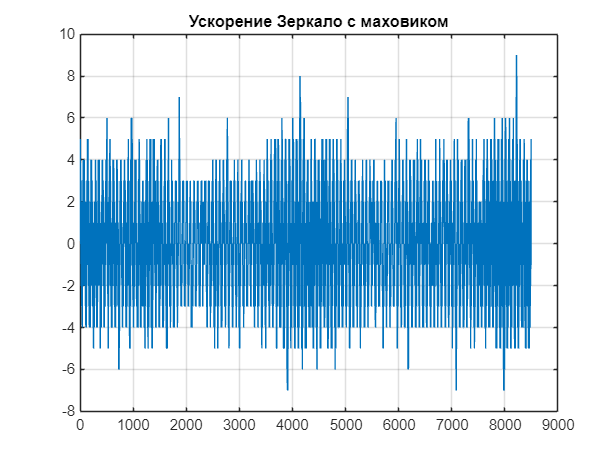


figure
plot(ScanAcc);
grid on
title("Ускорение Зеркало с маховиком");

Усреднение по 17-ти измерениям.

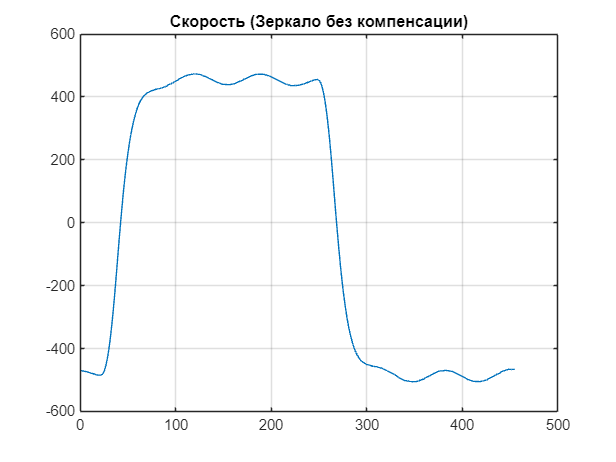

nm = 455; % число отсчетов в одном периоде
sumMirror = MirorMean(1:nm);
for i = 1:17
    sumMirror = sumMirror+MirorMean((nm*i)+1 : nm*(i+1));
end
plot(sumMirror/17)
title("Скорость (Зеркало без компенсации)")
grid on

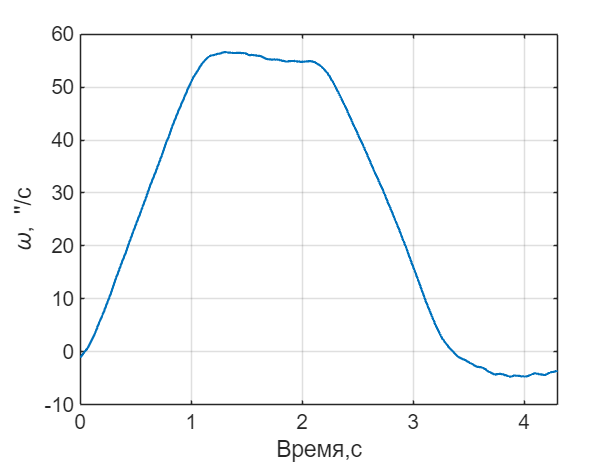

nt = 439 ;
sumTest = TestMomMean(1:nt);
for i = 1:10
    sumTest = sumTest + TestMomMean((nt*i)+1 : nt*(i+1));
end

sumTest = ((sumTest/17)+75)/3;
figure
plot(t(1:length(sumTest)),sumTest, "LineWidth",1.5)
grid on
grid on
xlim([0,4.3])
xlabel("Время,с", "FontSize",14)
ylabel("\omega, ''/c", "FontSize",14)
set(gca, 'FontSize', 14)   % задаёт размер шрифта для делений на осях
print(gcf, '../img/test-gyro-sum.png', '-dpng', '-r600')

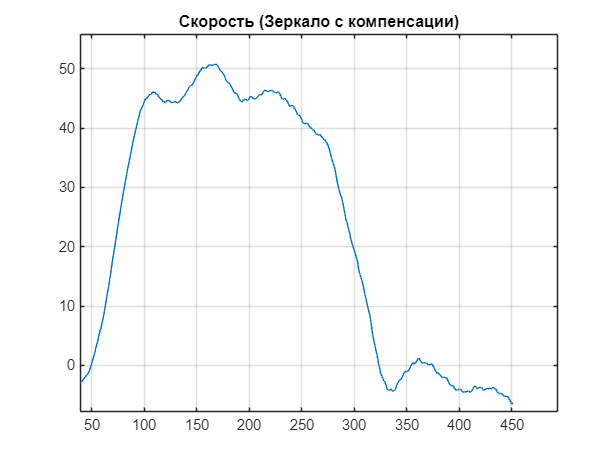



ns = 451;
sumScan = ScanMean(1:ns);
for i = 1:17
    sumScan = sumScan+ScanMean((ns*i)+1 : ns*(i+1));
end

plot(sumScan/17)
title("Скорость (Зеркало с компенсации)")
grid on

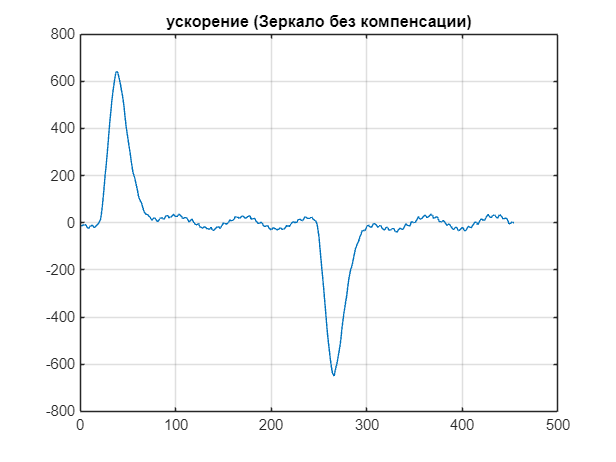

Macc = diff(sumMirror);
Tacc = diff(sumTest)/0.01;
Sacc = diff(sumScan);


plot(Macc);
grid on
title("ускорение (Зеркало без компенсации)")

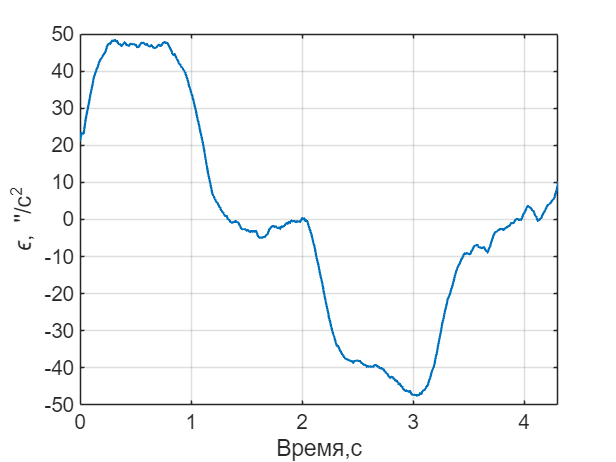

Tacc = smooth(Tacc,0.03)/1.2;
plot(t(1:438), Tacc, "LineWidth",1.5);

grid on
grid on
xlim([0,4.3])
yticks([-60:10:60])
xlabel("Время,с", "FontSize",14)
ylabel("\epsilon, ''/c^2", "FontSize",14)
set(gca, 'FontSize', 14)   % задаёт размер шрифта для делений на осях
print(gcf, '../img/test-gyro-acc.png', '-dpng', '-r600')
grid on

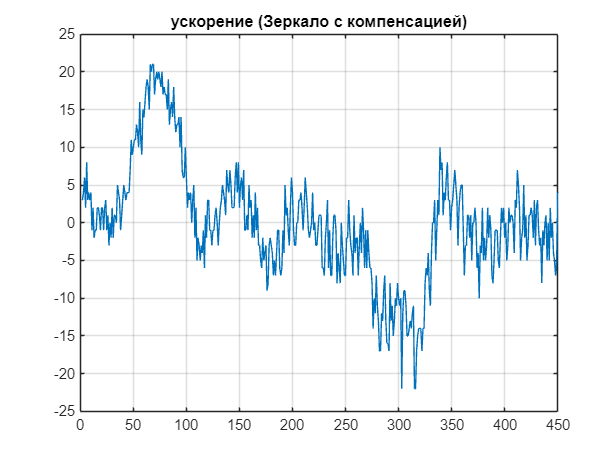


plot(Sacc);
grid on
title("ускорение (Зеркало с компенсацией)")